disp("Interpolation")

Interpolation


clc; clear;

% Equation
syms A B C Rs n
STeq = 1/(A + B*log(Rs) + C*log(Rs)^n)

$$STeq = \frac{1}{A+C\,{\log\left(\mathrm{Rs}\right)}^{n}+B\,\log\left(\mathrm{Rs}\right)}$$

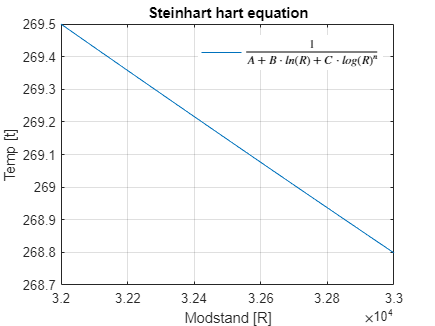

% Plot

A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;

n = 3;

Rs = linspace(32000, 33000, 1000);

STeq = 1./(A + B*log(Rs) + C*log(Rs).^(n-1) + D*log(Rs).^n);


plot(Rs, STeq), grid("on")
title("Steinhart hart equation")
legend("$\frac{1}{A + B\cdot ln(R) + C\cdot log(R)^n}$","Interpreter","latex","Box","off")
ylabel("Temp [t]")
xlabel("Modstand [R]")

clc; clear;

data1 = importdata("Log Data 17-04-2023 12.27.24.txt");
data2 = importdata("Log Data 17-04-2023 12.54.19.txt");
data3 = importdata("Log Data 17-04-2023 13.22.15.txt");
data4 = importdata("Log Data 17-04-2023 13.52.30.txt");
data5 = importdata("Log Data 17-04-2023 14.33.43.txt");
data6 = importdata("Log Data 17-04-2023 15.20.19.txt");

data1avr = mean(data1.data(:,2))

data1avr = 3.2209e+04

data2avr = mean(data2.data(:,2))

data2avr = 1.7220e+04

data3avr = mean(data3.data(:,2))

data3avr = 9.7413e+03

data4avr = mean(data4.data(:,2))

data4avr = 5.7722e+03

data5avr = mean(data5.data(:,2))

data5avr = 9.7277e+03

data6avr = mean(data6.data(:,2))

data6avr = 1.7194e+04



A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;

n = 3;


RsMean = [data1avr, data2avr, data3avr, data4avr, data5avr, data6avr]

RsMean = 1.0e+04 *

    3.2209    1.7220    0.9741    0.5772    0.9728    1.7194


RsMean = RsMean'

RsMean = 1.0e+04 *

    3.2209
    1.7220
    0.9741
    0.5772
    0.9728
    1.7194


STeqavr = 1./(A + B*log(RsMean) + C*log(RsMean).^(n-1) + D*log(RsMean).^n) - 273.15;


Rs = [data1.data(:,2);data2.data(:,2);data3.data(:,2);data4.data(:,2);data5.data(:,2);data6.data(:,2)];
Rs

Rs = 1.0e+04 *

    3.2218
    3.2196
    3.2249
    3.2236
    3.2202
    3.2278
    3.2178
    3.2226
    3.2150
    3.2241


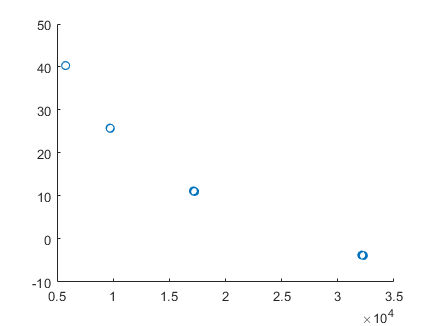

gauss = "1./(a + b*log(x) + c*log(x).^(n-1) + d*log(x).^n) - 273.15"

STeq = 1./(A + B*log(Rs) + C*log(Rs).^(n-1) + D*log(Rs).^n) - 273.15;


scatter(Rs, STeq)


gauss = "1./(a + b*log(x) + c*log(x).^(n-1) + d*log(x).^n) - 273.15"

gauss = "1./(a + b*log(x) + c*log(x).^(n-1) + d*log(x).^n) - 273.15"

T_Ref = linspace(-5, 40, length(STeq));
STeq

STeq =    -3.8051
   -3.7899
   -3.8275
   -3.8182
   -3.7939
   -3.8477
   -3.7766
   -3.8108
   -3.7569
   -3.8216


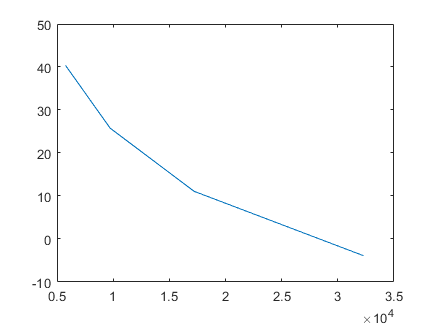

plot(Rs, STeq)

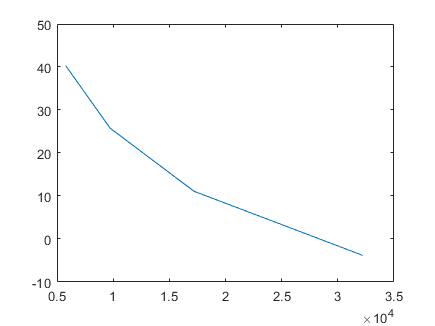

plot(RsMean, STeqavr)


mdl = fit(Rs, STeq, 'poly2')

mdl =      Linear model Poly2:
     mdl(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =   5.876e-08  (5.636e-08, 6.116e-08)
       p2 =   -0.003833  (-0.003928, -0.003738)
       p3 =       58.92  (58.16, 59.68)

mdlavr = fit(RsMean, STeqavr, 'poly2')

mdlavr =      Linear model Poly2:
     mdlavr(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =   5.876e-08  (2.908e-08, 8.845e-08)
       p2 =   -0.003833  (-0.005009, -0.002658)
       p3 =       58.92  (49.48, 68.36)

start = [A, B, C, D, n]

start =     0.0005    0.0004   -0.0000    0.0000    3.0000


mdl2 = fit(Rs, STeq, gauss, "Start", start)

mdl2 =      General model:
     mdl2(x) = 1./(a + b*log(x) + c*log(x).^(n-1) + d*log(x).^n) - 273.15
     Coefficients (with 95% confidence bounds):
       a =    0.000511  (0.000511, 0.000511)
       b =   0.0003717  (0.0003717, 0.0003717)
       c =  -1.278e-05  (-1.278e-05, -1.278e-05)
       d =   6.441e-07  (6.441e-07, 6.441e-07)
       n =           3  (3, 3)

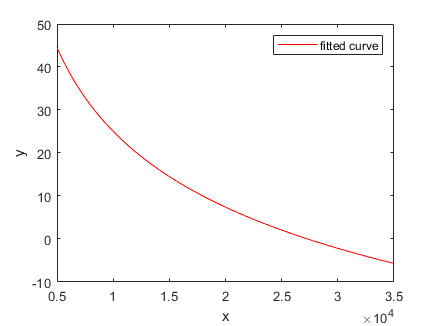

plot(mdl2)